Simulation of ACh sensor that should go to the paper.

% give this simulation a name
SimulationName='simulation_ACh_20221228_v2';
savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/Simulation/';

% create the simulation folder
cd(savefolder)
% mkdir(SimulationName)

% go to the simulation folder
filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20221228_v2/'

cd(filepath)

% load the dataset 
datapath = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221224AChsensorHEK001/'

datapath = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221224AChsensorHEK001/'

stateYao_file = "/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221224AChsensorHEK001/analysis_offset0_ROIadjusted_20221225.mat"

stateYao_file = "/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221224AChsensorHEK001/analysis_offset0_ROIadjusted_20221225.mat"


all_epochs = [2 3 4]; % all the epochs
drug_epochs = [2 3 4];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

CyclePositions = [1 2 3]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

cd(datapath);
load(stateYao_file);

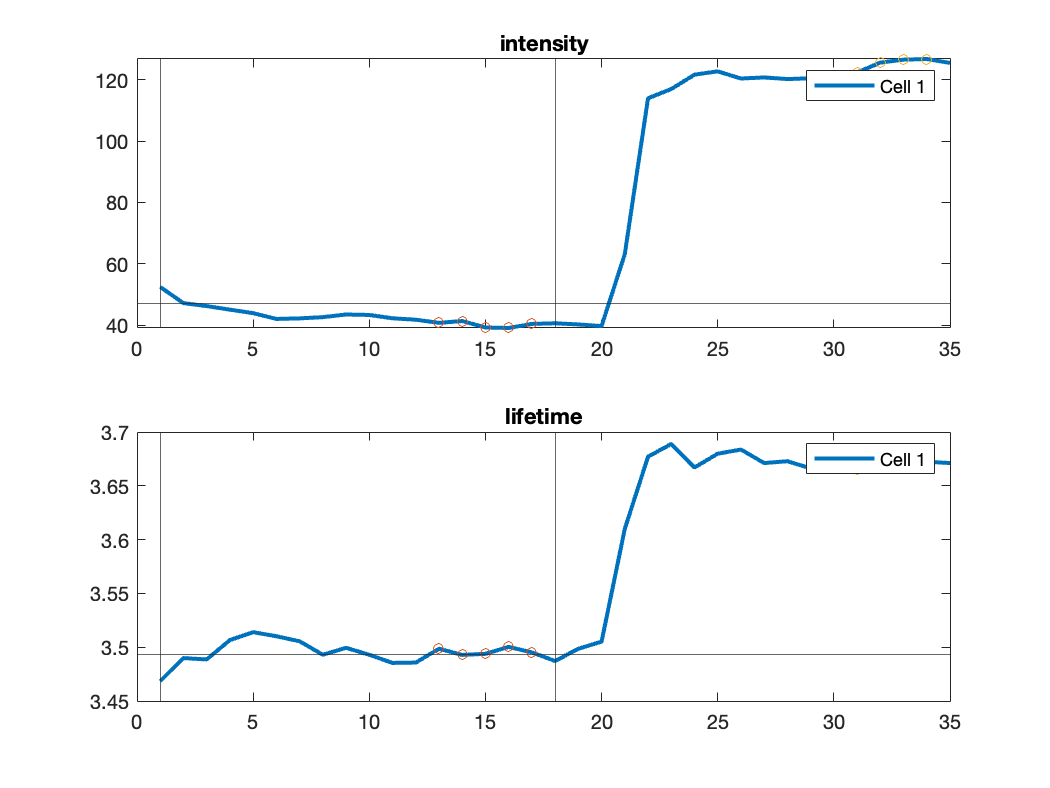

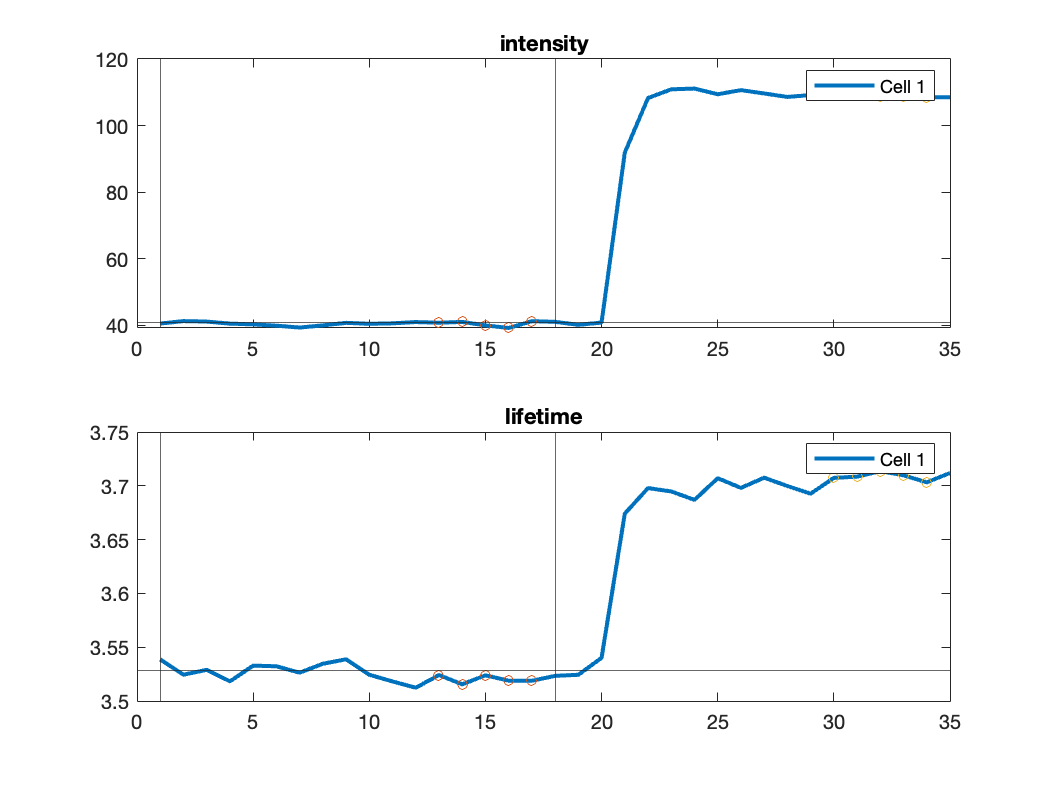

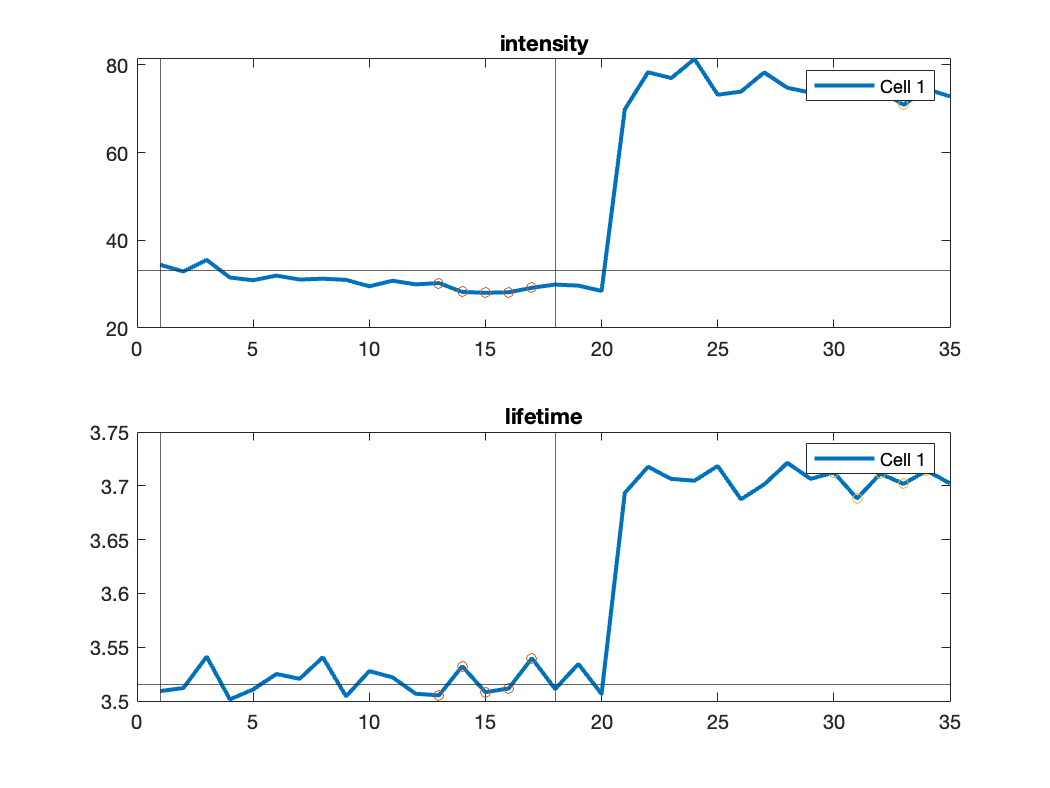

epoch_response_intensity_norm_all = 1×3 cell array
    {2×1 double}    {2×1 double}    {2×1 double}


epoch_response_lft_norm_all = 1×3 cell array
    {2×1 double}    {2×1 double}    {2×1 double}


epoch_response_intensity_all = 1×3 cell array
    {2×1 double}    {2×1 double}    {2×1 double}


epoch_response_lft_all = 1×3 cell array
    {2×1 double}    {2×1 double}    {2×1 double}


% revise the lifetime calculation if it's using the previous version of
% mask definition in stateYao;
% Plot the lifetime trace to select the baseline and ACh acquisitions

Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
CalculateROIBasedOnTopPixels(5, 0.66,CyclePositions)
[lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
[epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)

% based on the plot, select the representative baseline and ACh images

baseline_index_cycle1 = 17;
ACh_index_cycle1 = 34;
baseline_index_cycle2 = 17;
ACh_index_cycle2 = 34;
baseline_index_cycle3 = 17;
ACh_index_cycle3 = 34;
baseline_acq_cycle1 = stateYao.CyclePositions(baseline_index_cycle1,1)

baseline_acq_cycle1 = 55

ACh_acq_cycle1 = stateYao.CyclePositions(ACh_index_cycle1,1)

ACh_acq_cycle1 = 106

baseline_acq_cycle2 = stateYao.CyclePositions(baseline_index_cycle2,2)

baseline_acq_cycle2 = 56

ACh_acq_cycle2 = stateYao.CyclePositions(ACh_index_cycle2,2)

ACh_acq_cycle2 = 107

baseline_acq_cycle3 = stateYao.CyclePositions(baseline_index_cycle3,3)

baseline_acq_cycle3 = 57

ACh_acq_cycle3 = stateYao.CyclePositions(ACh_index_cycle3,3)

ACh_acq_cycle3 = 108

% load the file of ACh sensor under ACh 100 uM condition
cd(datapath);
ACh_spc_file_cycle1 = [datapath stateYao.baseName 'FLIM' num2str(ACh_acq_cycle1) '.mat']

ACh_spc_file_cycle1 = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221224AChsensorHEK001/20221224AChsensorHEK001FLIM106.mat'

load(ACh_spc_file_cycle1);

% based on the acq number, load the corresponding ROI mask,
spc_lifetimes_cycle1 = zeros(256,1);
imageMods = spcSave.imageMods{1};
for iCell = 1:size(stateYao.images.I_ROI_stack{1}{ACh_index_cycle1},3)
    mask = stateYao.images.I_ROI_stack{1}{ACh_index_cycle1}(:,:,iCell);
    mask_sum1 = sum(sum(mask));
%     mask = stateYao.I_ROI_stack_TopPixels{1}{ACh_index_cycle1}{iCell};
    for i_x = 1:128
        for i_y = 1:128
            if mask(i_x,i_y)==1
                spc_lifetimes_cycle1 = spc_lifetimes_cycle1 + imageMods(:,i_x, i_y);
            end
        end
    end
end


ACh_spc_file_cycle2 = [datapath stateYao.baseName 'FLIM' num2str(ACh_acq_cycle2) '.mat']

ACh_spc_file_cycle2 = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221224AChsensorHEK001/20221224AChsensorHEK001FLIM107.mat'

load(ACh_spc_file_cycle2);

imageMods = spcSave.imageMods{1};
spc_lifetimes_cycle2 = zeros(256,1);
for iCell = 1:size(stateYao.images.I_ROI_stack{2}{ACh_index_cycle2},3)
    mask = stateYao.images.I_ROI_stack{2}{ACh_index_cycle2}(:,:,iCell);
    mask_sum2 = sum(sum(mask));
%     mask = stateYao.I_ROI_stack_TopPixels{2}{ACh_index_cycle2}{iCell};
    for i_x = 1:128
        for i_y = 1:128
            if mask(i_x,i_y)==1
                spc_lifetimes_cycle2 = spc_lifetimes_cycle2 + imageMods(:,i_x, i_y);
            end
        end
    end
end

ACh_spc_file_cycle3 = [datapath stateYao.baseName 'FLIM' num2str(ACh_acq_cycle3) '.mat']

ACh_spc_file_cycle3 = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221224AChsensorHEK001/20221224AChsensorHEK001FLIM108.mat'

load(ACh_spc_file_cycle3)

imageMods = spcSave.imageMods{1};
spc_lifetimes_cycle3 = zeros(256,1);
for iCell = 1:size(stateYao.images.I_ROI_stack{3}{ACh_index_cycle3},3)
    mask = stateYao.images.I_ROI_stack{3}{ACh_index_cycle3}(:,:,iCell);
    mask_sum3 = sum(sum(mask));
%     mask = stateYao.I_ROI_stack_TopPixels{3}{ACh_index_cycle3}{iCell};
    for i_x = 1:128
        for i_y = 1:128
            if mask(i_x,i_y)==1
                spc_lifetimes_cycle3 = spc_lifetimes_cycle3 + imageMods(:,i_x, i_y);
            end
        end
    end
end


mask_sum_size = sum([mask_sum1 mask_sum2 mask_sum3])

mask_sum_size = 8413

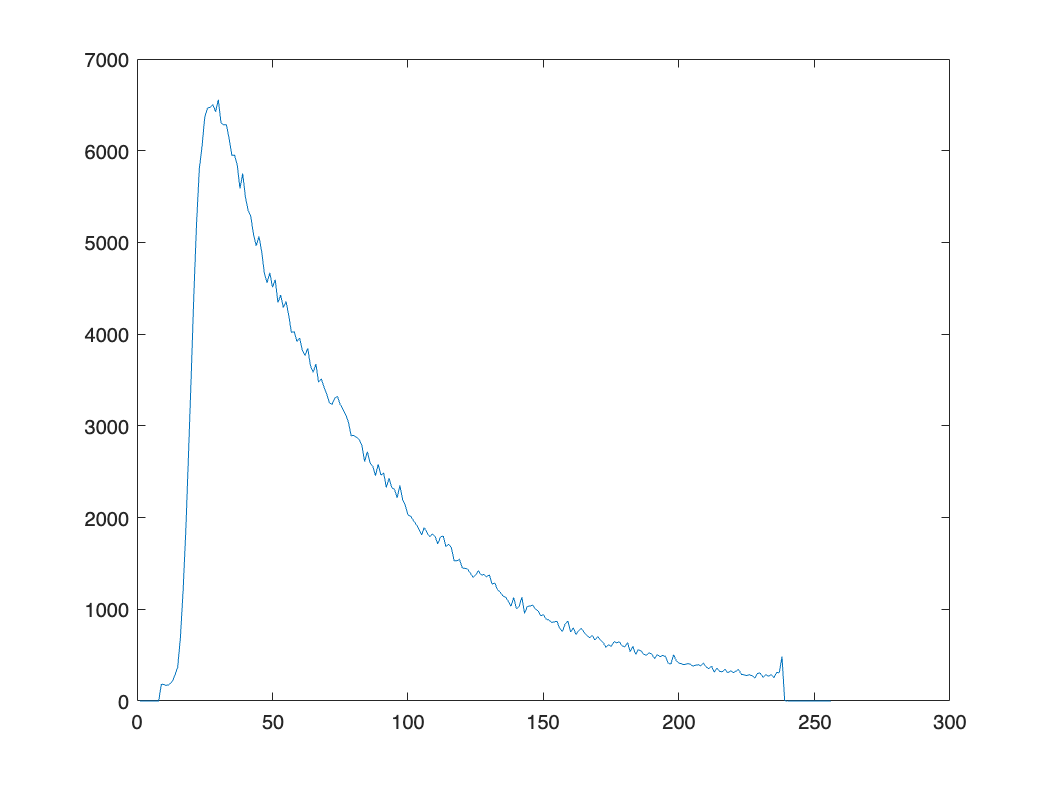

spc_lifetimes = spc_lifetimes_cycle1 + spc_lifetimes_cycle2 + spc_lifetimes_cycle3;

figure
plot(spc_lifetimes)


spc.lifetimes{1} = spc_lifetimes'

spc = struct with fields:
         switchess: {[1×1 struct]  [1×1 struct]}
     GUI_switchess: [1×1 struct]
              fits: {[1×1 struct]}
          GUI_fits: [1×1 struct]
          filename: '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221224AChsensorHEK001/20221224AChsensorHEK001FLIM107.mat'
              GUIS: [1×1 struct]
          datainfo: [1×1 struct]
               fit: [1×1 struct]
          switches: [1×1 struct]
         imageMods: {[256×128×128 double]}
      originalFile: 'C:\Users\User\Desktop\Pingchuan\2022Fall\20221224AChsensorHEK001\20221224AChsensorHEK001FLIM107.mat'
           SPCdata: [1×1 struct]
    imageModSlices: {}
       maxProjects: {[]}
         lifetimes: {[0 0 0 0 0 0 0 0 184 179 169 182 213 280 367 685 1195 1849 2683 3540 4450 5222 5803 6048 6364 6465 6475 6501 6425 6555 6303 6283 6284 6130 5950 5952 5844 5587 5751 5496 5352 5282 5085 4963 5064 4904 4662 4560 4669 4511 4592 4344 … ]}
              size: [256 128 128]
          projects: {

spc_lifetimes_trans = spc_lifetimes';

% move the corresponding prf to this folder, load this prf and do the
% fitting
cd(filepath)
copyfile /Volumes/yaochen/Active/Pingchuan/prf/20221224_prf_bottomgreen_PM.mat prf.mat

% after doing the fitting, output the fitting parameters

p1_ACh=spc.fits{1,1}.beta1/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p1_ACh = 0.9046

p2_ACh=spc.fits{1,1}.beta3/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p2_ACh = 0.0954

tau1_ACh=spc.fits{1,1}.beta2

tau1_ACh = 2.8808

tau2_ACh=spc.fits{1,1}.beta4

tau2_ACh = 0.4631

delta_peak_time=spc.fits{1,1}.beta5

delta_peak_time = -0.0748

SHG=spc.fits{1,1}.beta6

SHG = 0

samplesize_ACh=sum(spc.lifetimes{1})

samplesize_ACh = 454754

SHG_proportion=SHG/samplesize_ACh

SHG_proportion = 0

figureoffset=spc.switchess{1,1}.figOffset

figureoffset = 0.2052

backcorr=spc.fits{1,1}.backCorr

backcorr = 53.8176

chisq = spc.fits{1,1}.redchisq

chisq = 1.5827


% calculate the empirical lifetime from the histogram, considering the
% first 8 and last 8 channels are forced to be 0, and considering the
% fitting range.
lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
nsPerPoint=spc.datainfo.psPerUnit/1000

nsPerPoint = 0.0489

range=round([spc.fits{1,1}.fitstart spc.fits{1,1}.fitend]/nsPerPoint)

range =     10   235


weight_n_lft=lft_steps.*spc_lifetimes_trans(range(1):range(2));
empirical_lft_ACh=sum(weight_n_lft)/sum(spc_lifetimes_trans(range(1):range(2)))

empirical_lft_ACh = 0.0488


% also export the histogram
n_exp_ACh=spc.lifetimes{1};
n_exp_ACh_norm = n_exp_ACh/max(n_exp_ACh);
ACh_peak = find(n_exp_ACh == max(n_exp_ACh))

ACh_peak = 30


% calculate the empirical lifetime from the fitted curve


lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
weight_n_lft=lft_steps.*spc.fits{1,1}.curve';
empirical_lft_ACh_curve=sum(weight_n_lft)/sum(spc.fits{1,1}.curve')

empirical_lft_ACh_curve = 3.2482

n_exp_ACh_curve = spc.fits{1,1}.curve';

% save the fitting parameters
cd(filepath)
save('fitting_parameters.mat','p1_ACh','p2_ACh','tau1_ACh','tau2_ACh','delta_peak_time','SHG','samplesize_ACh','backcorr','empirical_lft_ACh','empirical_lft_ACh_curve','n_exp_ACh','n_exp_ACh_curve', 'range')

Error using save
Variable 'n_exp_ACh_curve' not found.

load('/Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20221227/fitting_parameters.mat')

% adjust the prf based on the delta peak time
% comment more the what the interpolation does and why doing that
cd(filepath)
load('prf.mat')
x=1:1:256;
prf_interp1=interp1(x,prf,x+(delta_peak_time/(12.5/256)),'linear');
prf_interp1(isnan(prf_interp1)) = 0;
prf_peak_ACh=find(prf_interp1==max(prf_interp1))

prf_peak_ACh = 20

find(prf==max(prf))

ans = 19

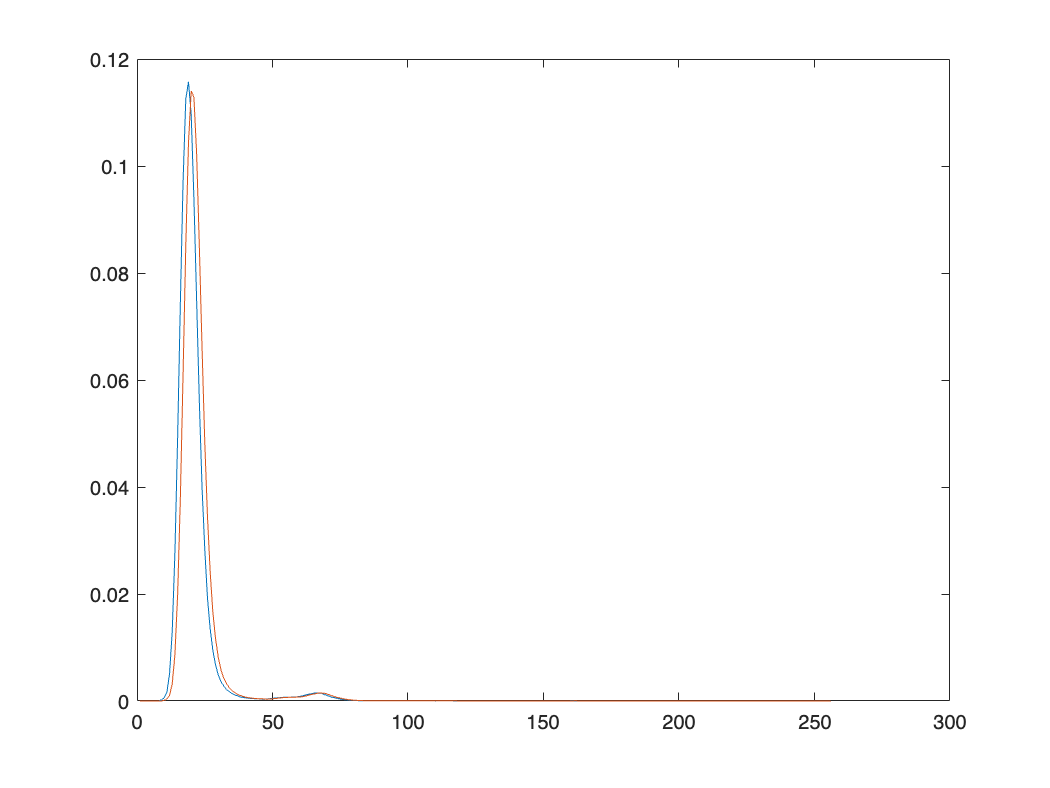


figure
plot(prf)
hold on
plot(prf_interp1)

% save this prf for future use
prf=prf_interp1;
prf_interp1_name='prf_ACh_interp1.mat';
save(prf_interp1_name,'prf')

% select a ROI or two, fix the offset at 0 for empirical lifetime
% find the corresponding functions to calculate the roi lifetime

global offset fixedoffset
fixedoffset=1;
offset=0;
spc_adjustTauOffset(1)

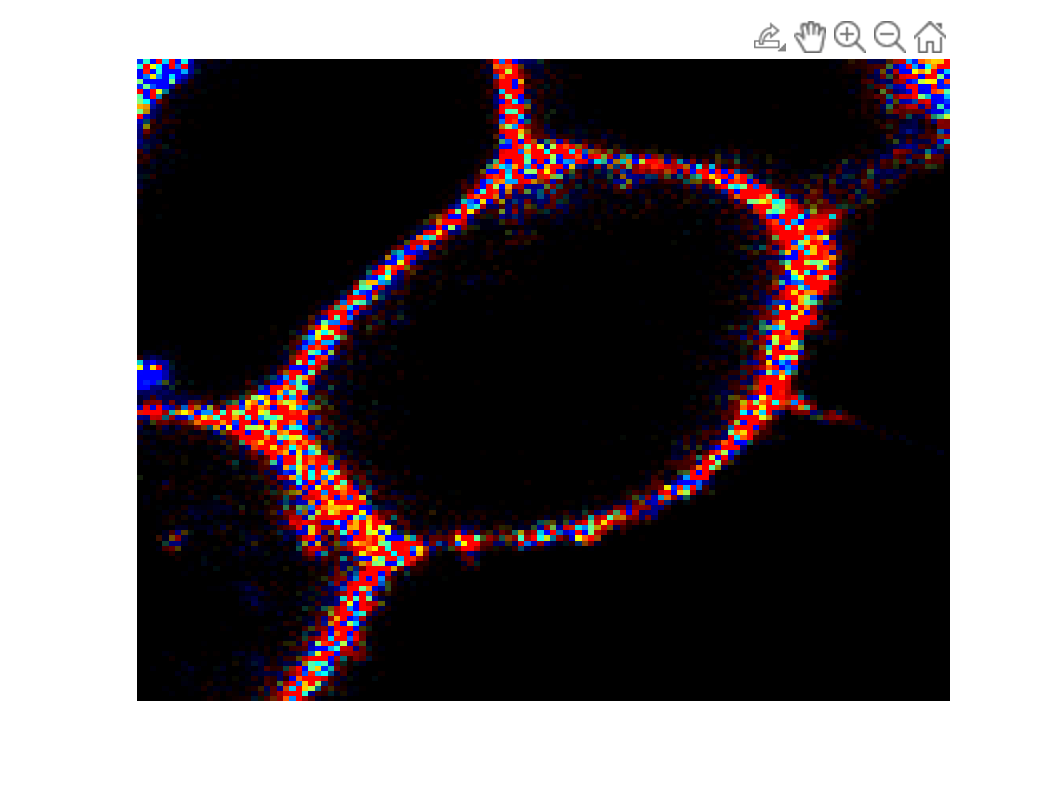

chan=1;

figure
image(spc.rgbLifetimes{chan});
axis off;

cd(filepath)
saveas(gcf, 'ACh_lft.fig')

ACh_spc_file_cycle1 = [datapath stateYao.baseName 'FLIM' num2str(ACh_acq_cycle1) '.mat']

ACh_spc_file_cycle1 = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221224AChsensorHEK001/20221224AChsensorHEK001FLIM106.mat'

spc_openCurves(ACh_spc_file_cycle1)

Reading /Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221224AChsensorHEK001/20221224AChsensorHEK001FLIM106.mat


spc_adjustTauOffset(1)

icycle = 1;
iCell = 1;
photoncount_ACh_mean1 = Yao_calc_Projection(spc.projects{1}, stateYao.I_ROI_stack_TopPixels{icycle}{ACh_index_cycle1}{iCell})

photoncount_ACh_mean1 = 126.7186

lft_ACh1=Yao_calc_Lifetime(spc.projects{1}, spc.lifetimeMaps{1}, stateYao.I_ROI_stack_TopPixels{icycle}{ACh_index_cycle1}{iCell})

lft_ACh1 = 3.2342

ROIsize_ACh1=sum(sum(stateYao.I_ROI_stack_TopPixels{icycle}{ACh_index_cycle1}{iCell}))

ROIsize_ACh1 = 1322

photoncount_ACh1 = photoncount_ACh_mean1 * ROIsize_ACh1

photoncount_ACh1 = 167522

ACh_spc_file_cycle2 = [datapath stateYao.baseName 'FLIM' num2str(ACh_acq_cycle2) '.mat']

ACh_spc_file_cycle2 = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221224AChsensorHEK001/20221224AChsensorHEK001FLIM107.mat'

spc_openCurves(ACh_spc_file_cycle2)

Reading /Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221224AChsensorHEK001/20221224AChsensorHEK001FLIM107.mat


spc_adjustTauOffset(1)

icycle = 2;
iCell = 1;
photoncount_ACh_mean2 = Yao_calc_Projection(spc.projects{1}, stateYao.I_ROI_stack_TopPixels{icycle}{ACh_index_cycle2}{iCell})

photoncount_ACh_mean2 = 108.5297

lft_ACh2=Yao_calc_Lifetime(spc.projects{1}, spc.lifetimeMaps{1}, stateYao.I_ROI_stack_TopPixels{icycle}{ACh_index_cycle2}{iCell})

lft_ACh2 = 3.2645

ROIsize_ACh2=sum(sum(stateYao.I_ROI_stack_TopPixels{icycle}{ACh_index_cycle2}{iCell}))

ROIsize_ACh2 = 1331

photoncount_ACh2 = photoncount_ACh_mean2 * ROIsize_ACh2

photoncount_ACh2 = 144453

ACh_spc_file_cycle3 = [datapath stateYao.baseName 'FLIM' num2str(ACh_acq_cycle3) '.mat']
spc_openCurves(ACh_spc_file_cycle3)
spc_adjustTauOffset(1)

icycle = 3;
iCell = 1;
photoncount_ACh_mean3 = Yao_calc_Projection(spc.projects{1}, stateYao.I_ROI_stack_TopPixels{icycle}{ACh_index_cycle3}{iCell})

photoncount_ACh_mean3 = 28.1878

lft_ACh3 = Yao_calc_Lifetime(spc.projects{1}, spc.lifetimeMaps{1}, stateYao.I_ROI_stack_TopPixels{icycle}{ACh_index_cycle3}{iCell})

lft_ACh3 = 3.2776

ROIsize_ACh3=sum(sum(stateYao.I_ROI_stack_TopPixels{icycle}{ACh_index_cycle3}{iCell}))

ROIsize_ACh3 = 980

photoncount_ACh3 = photoncount_ACh_mean3 * ROIsize_ACh3

photoncount_ACh3 = 27624

% go to another file of baseline condition
baseline_spc_file_cycle1 = [datapath stateYao.baseName 'FLIM0' num2str(baseline_acq_cycle1) '.mat']

baseline_spc_file_cycle1 = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221224AChsensorHEK001/20221224AChsensorHEK001FLIM055.mat'

spc_openCurves(baseline_spc_file_cycle1)

Reading /Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221224AChsensorHEK001/20221224AChsensorHEK001FLIM055.mat


spc_adjustTauOffset(1)


icycle = 1;
iCell = 1;
photoncount_baseline_mean1 = Yao_calc_Projection(spc.projects{1}, stateYao.I_ROI_stack_TopPixels{icycle}{baseline_index_cycle1}{iCell})

photoncount_baseline_mean1 = 40.4738

lft_baseline1=Yao_calc_Lifetime(spc.projects{1}, spc.lifetimeMaps{1}, stateYao.I_ROI_stack_TopPixels{icycle}{baseline_index_cycle1}{iCell})

lft_baseline1 = 3.0563

ROIsize_baseline1=sum(sum(stateYao.I_ROI_stack_TopPixels{icycle}{baseline_index_cycle1}{iCell}))

ROIsize_baseline1 = 1281

photoncount_baseline1 = round(photoncount_baseline_mean1 * ROIsize_baseline1)

photoncount_baseline1 = 51847

baseline_spc_file_cycle2 = [datapath stateYao.baseName 'FLIM0' num2str(baseline_acq_cycle2) '.mat']

baseline_spc_file_cycle2 = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221224AChsensorHEK001/20221224AChsensorHEK001FLIM056.mat'

spc_openCurves(baseline_spc_file_cycle2)

Reading /Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221224AChsensorHEK001/20221224AChsensorHEK001FLIM056.mat


spc_adjustTauOffset(1)


icycle = 2;
iCell = 1;
photoncount_baseline_mean2 = Yao_calc_Projection(spc.projects{1}, stateYao.I_ROI_stack_TopPixels{icycle}{baseline_index_cycle2}{iCell})

photoncount_baseline_mean2 = 41.1995

lft_baseline2 = Yao_calc_Lifetime(spc.projects{1}, spc.lifetimeMaps{1}, stateYao.I_ROI_stack_TopPixels{icycle}{baseline_index_cycle2}{iCell})

lft_baseline2 = 3.0798

ROIsize_baseline2 = sum(sum(stateYao.I_ROI_stack_TopPixels{icycle}{baseline_index_cycle2}{iCell}))

ROIsize_baseline2 = 1303

photoncount_baseline2 = round(photoncount_baseline_mean2 * ROIsize_baseline2)

photoncount_baseline2 = 53683

baseline_spc_file_cycle3 = [datapath stateYao.baseName 'FLIM0' num2str(baseline_acq_cycle3) '.mat']
spc_openCurves(baseline_spc_file_cycle3)
spc_adjustTauOffset(1)


icycle = 3;
iCell = 1;
photoncount_baseline_mean3 = Yao_calc_Projection(spc.projects{1}, stateYao.I_ROI_stack_TopPixels{icycle}{baseline_index_cycle3}{iCell})

photoncount_baseline_mean3 = 8.9289

lft_baseline3 = Yao_calc_Lifetime(spc.projects{1}, spc.lifetimeMaps{1}, stateYao.I_ROI_stack_TopPixels{icycle}{baseline_index_cycle3}{iCell})

lft_baseline3 = 3.0783

ROIsize_baseline3 = sum(sum(stateYao.I_ROI_stack_TopPixels{icycle}{baseline_index_cycle3}{iCell}))

ROIsize_baseline3 = 971

photoncount_baseline3 = round(photoncount_baseline_mean3 * ROIsize_baseline3)

photoncount_baseline3 = 8670

lft_ACh_all = [lft_ACh1 lft_ACh2 lft_ACh3]

lft_ACh_all =     3.2342    3.2645    3.2776


lft_baseline_all = [lft_baseline1 lft_baseline2 lft_baseline3]

lft_baseline_all =     3.0563    3.0798    3.0783



ROIsize_ACh_all = [ROIsize_ACh1 ROIsize_ACh2 ROIsize_ACh3]

ROIsize_ACh_all =         1322        1331         980


ROIsize_baseline_all = [ROIsize_baseline1 ROIsize_baseline2 ROIsize_baseline3]

ROIsize_baseline_all =         1281        1303         971



photoncount_ACh_all = [photoncount_ACh1 photoncount_ACh2 photoncount_ACh3]

photoncount_ACh_all =       167522      144453       27624


photoncount_baseline_all = [photoncount_baseline1 photoncount_baseline2 photoncount_baseline3]

photoncount_baseline_all =        51847       53683        8670



ROIsize_ACh = round(mean(ROIsize_ACh_all))

ROIsize_ACh = 1211

ROIsize_baseline = round(mean(ROIsize_baseline_all))

ROIsize_baseline = 1185


photoncount_ACh_all./ROIsize_ACh_all

ans =   126.7186  108.5297   28.1878



photoncount_ACh = round(mean(photoncount_ACh_all))

photoncount_ACh = 113200

photoncount_baseline = round(mean(photoncount_baseline_all))

photoncount_baseline = 38067


photons_per_pixel_ACh = round(sum(photoncount_ACh_all)/sum(ROIsize_ACh_all))

photons_per_pixel_ACh = 93

photons_per_pixel_baseline = round(sum(photoncount_baseline_all)/sum(ROIsize_baseline_all))

photons_per_pixel_baseline = 32


photoncount_ACh = ROIsize_ACh * photons_per_pixel_ACh

photoncount_ACh = 112623

photoncount_baseline = ROIsize_ACh * photons_per_pixel_baseline

photoncount_baseline = 38752

% Name the population of double exponential decay
PopulationName='ACh_population_20221228'

PopulationName = 'ACh_population_20221228'

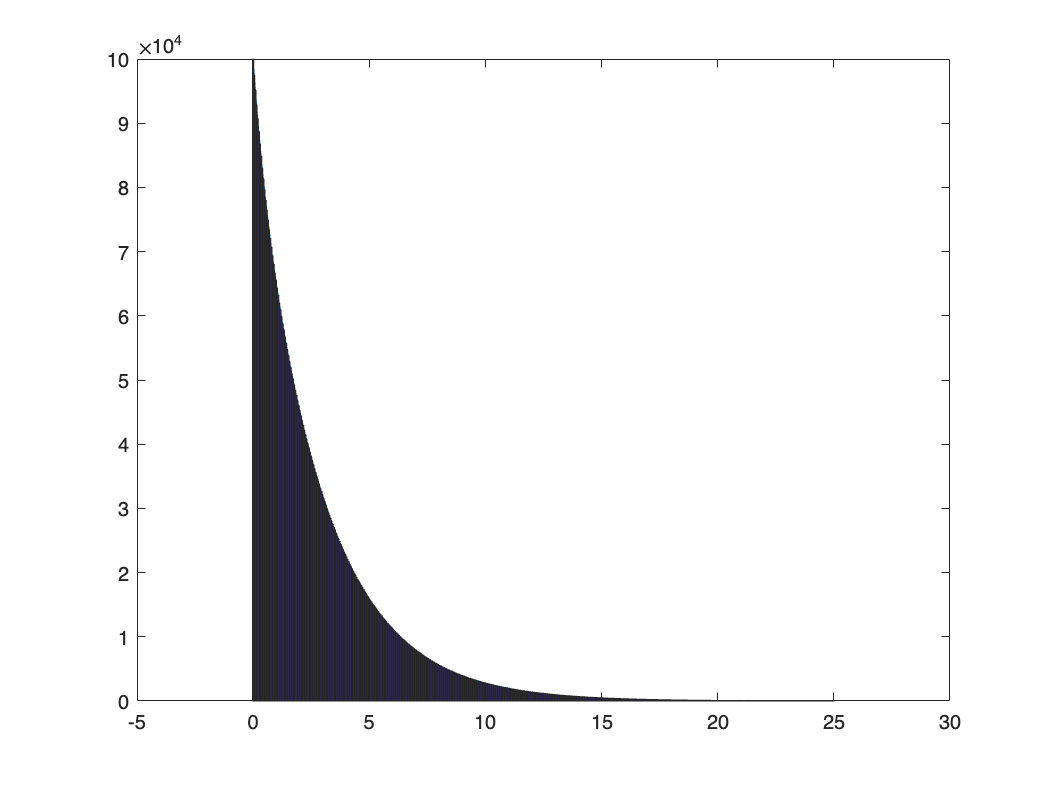

     5465755



% generate the double exponential population, no SHG added, 512 channels
GenPop512_Ach(100000,p1_ACh,p2_ACh,tau1_ACh,tau2_ACh,PopulationName)

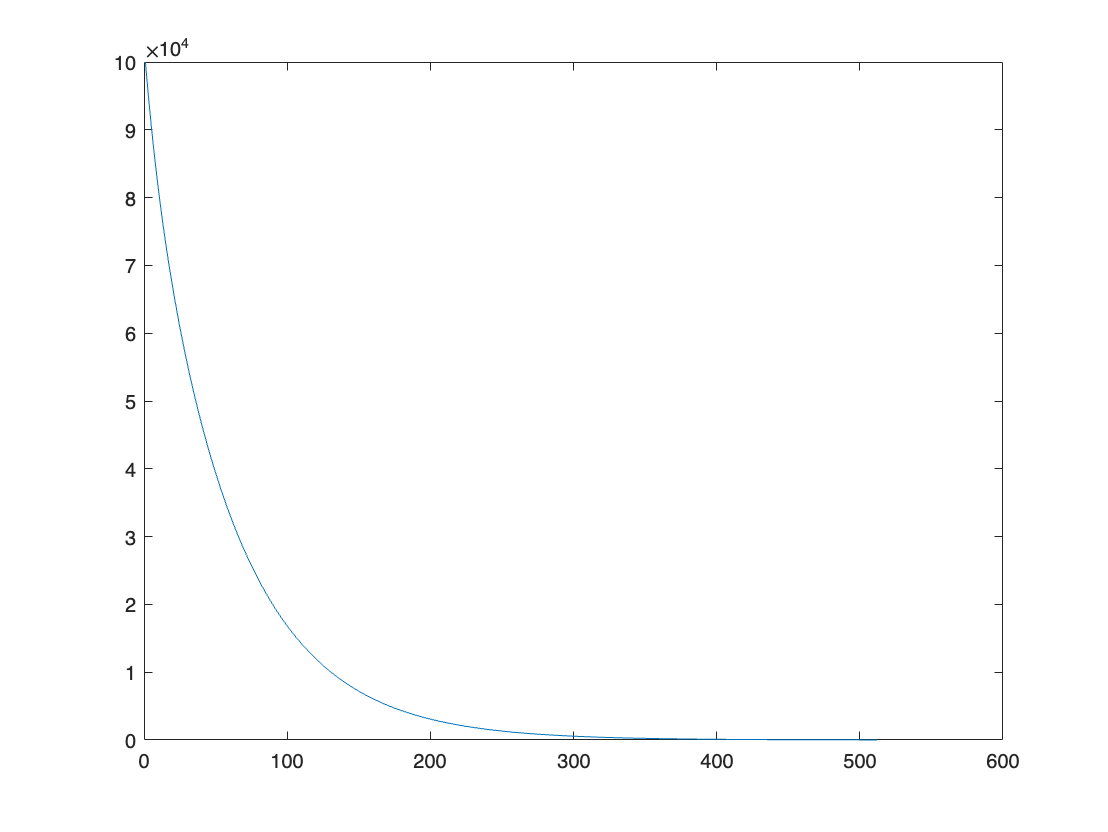

%% Test the population generated is ok. Calculate the analytical lft for each population

load(PopulationName)
xsim=linspace(0,25,512);
[n,xout]=hist(Population, xsim);
figure
plot(n)

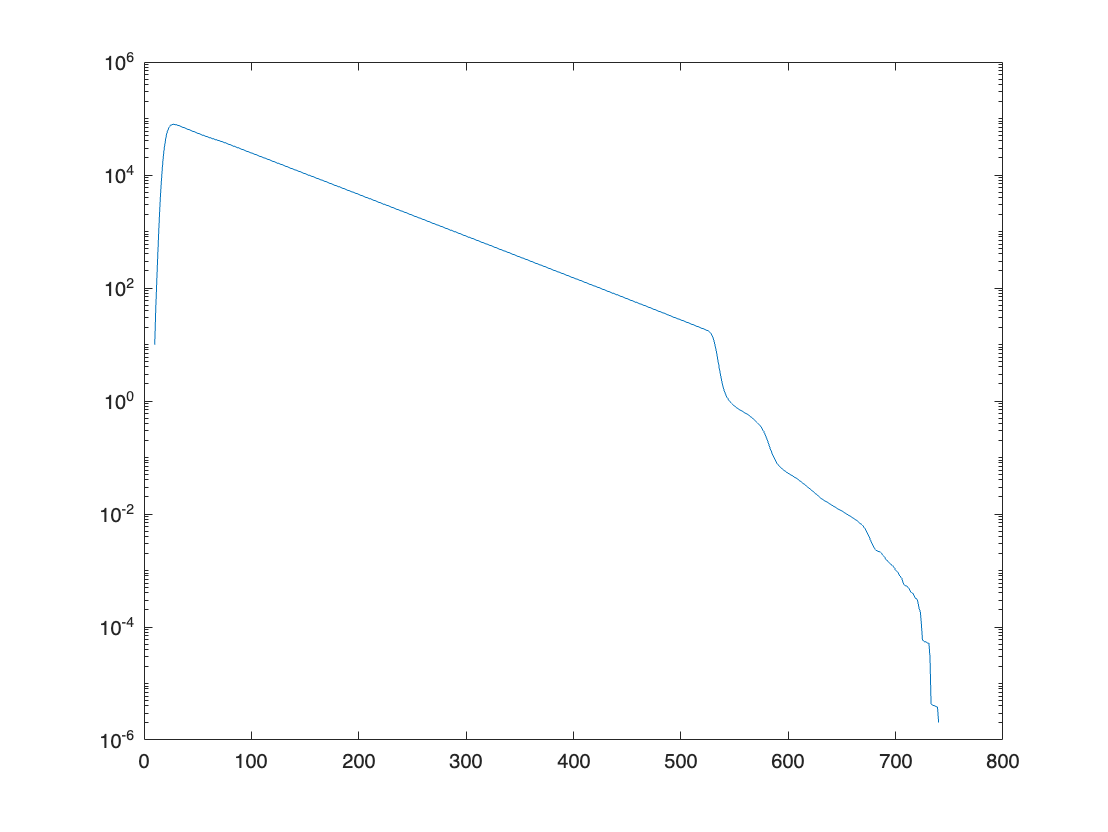


% convolute the double exponential curve use the new prf
conv_n=conv(n,prf);
figure % plot right after the convolution
semilogy(conv_n)

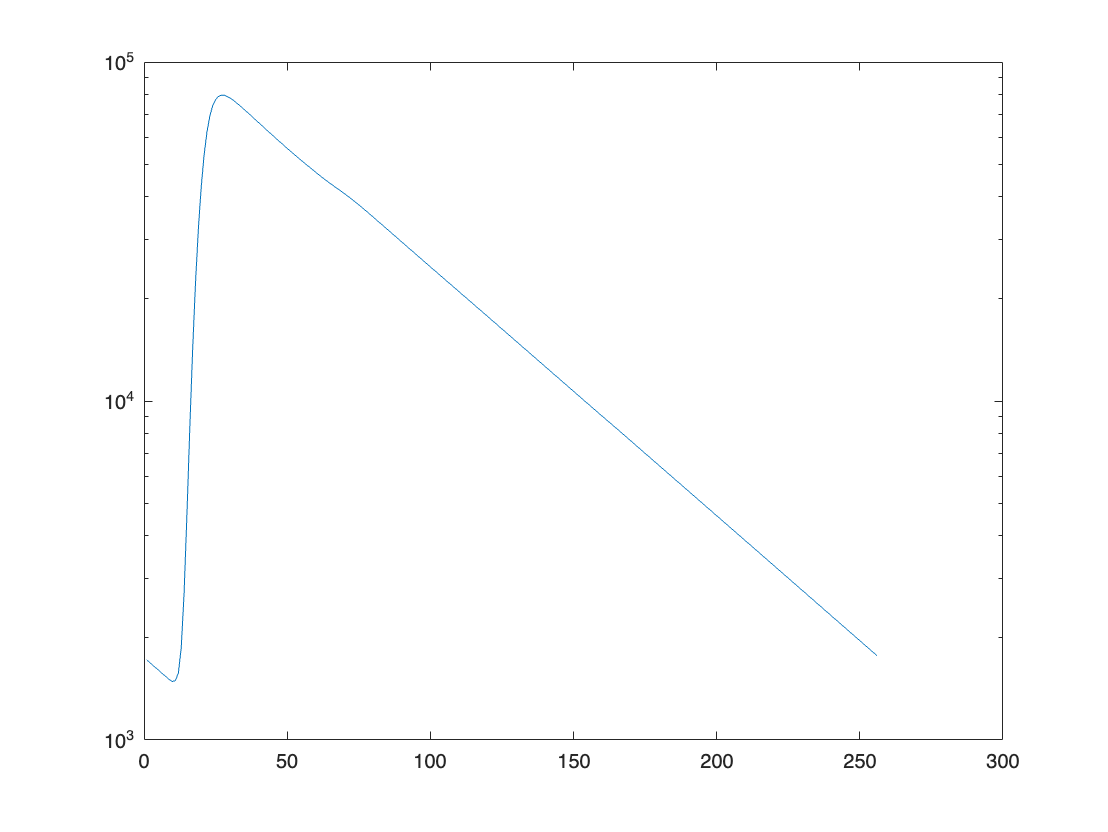


conv_n1=conv_n(257:512);
conv_n_final=conv_n(1:256)+conv_n1; % wrap around

figure
semilogy(conv_n_final) % plot after wrap around


% before background correction, calculate the empirical lifetime

lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
weight_n_lft=lft_steps.*conv_n_final(range(1):range(2));
empirical_lft=sum(weight_n_lft)/sum(conv_n_final(range(1):range(2)))

empirical_lft = 3.1825


% add the background correction term, calculate the empirical lifetime
backcorr_ratio=backcorr/samplesize_ACh;
backcorr_ACh=sum(conv_n_final)*backcorr_ratio

backcorr_ACh = 646.7934

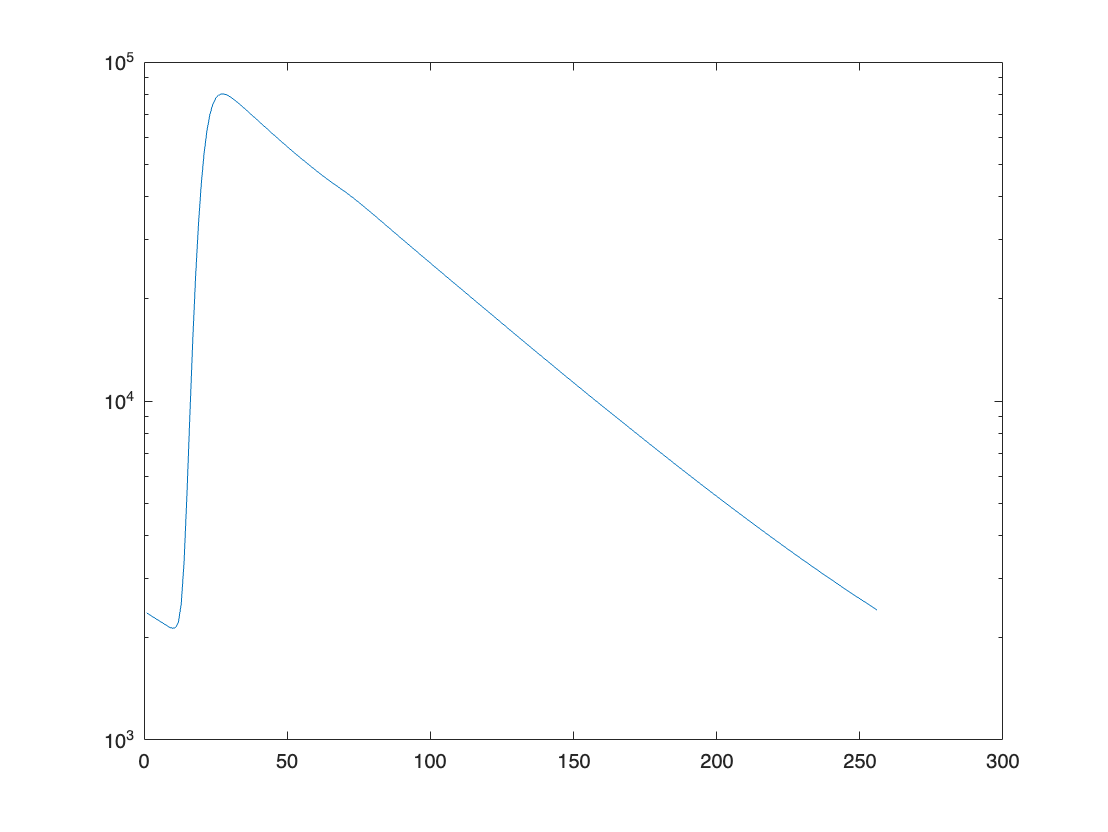

conv_n_final_corr=conv_n_final+backcorr_ACh;
figure
semilogy(conv_n_final_corr)


% from the fitted curve: empirical_lft_ACh_curve = 3.4850
weight_n_lft=lft_steps.*conv_n_final_corr(range(1):range(2));
empirical_lft_PopNoSHG=sum(weight_n_lft)/sum(conv_n_final_corr(range(1):range(2)))

empirical_lft_PopNoSHG = 3.2447



% so generation of the population is good. Then move to simulation

copyfile /Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221224autofluoHEK001/autofluorescence_20230102.mat autofluorescence.mat

load('autofluorescence.mat')

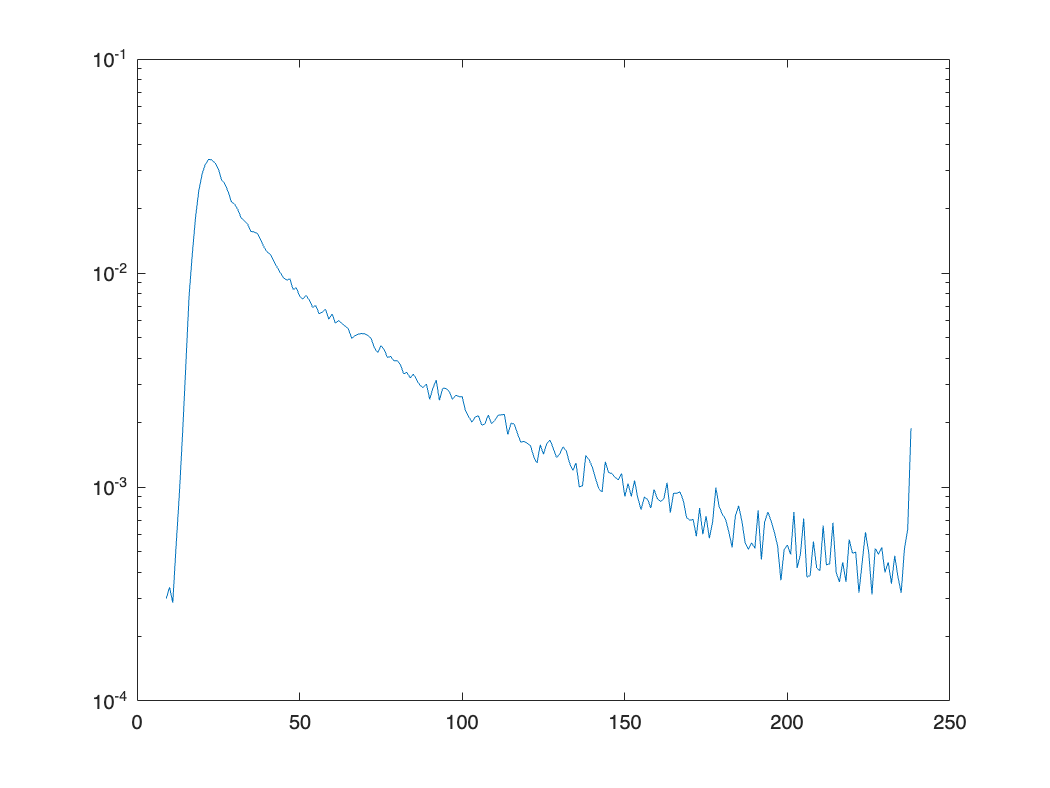

figure
semilogy(AF_histogram_norm)


% autofluo_peak = find(AF_histogram_norm == max(AF_histogram_norm))
% AF_plot = mask_sum_size*AF_histogram_norm
% AF_peak_norm = AF_plot/max(AF_plot)

lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
weight_n_lft=lft_steps.*AF_histogram_norm(range(1):range(2));
empirical_lft_autofluo=sum(weight_n_lft)/sum(AF_histogram_norm(range(1):range(2)))

empirical_lft_autofluo = 2.2268

% test the simulation, if no dark count, no afterpulse, no
% autofluorescence, simulate and then add background correction, the
% lifetime should be similiar to the fitted curve
DC=0;
afterpulse=0;
AF=0;
SaveName='test_sim.mat'

SaveName = 'test_sim.mat'

FLIMsim512_Ach(samplesize_ACh, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName)

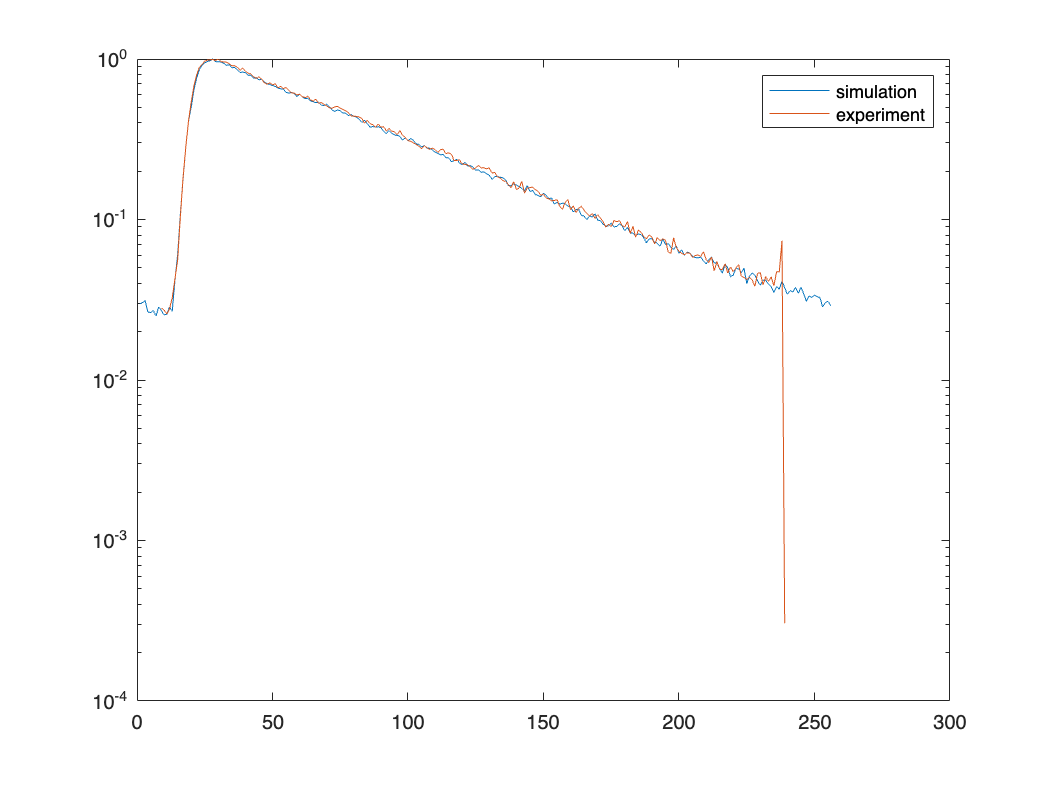

load(SaveName)
figure
% semilogy(n_final)

n_final=n_final+backcorr;
% hold on
semilogy(n_final/(max(n_final)))

hold on
semilogy(n_exp_ACh/max(n_exp_ACh))
legend('simulation','experiment')


lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
weight_n_lft=lft_steps.*n_final(range(1):range(2));
empirical_lft_curveonly=sum(weight_n_lft)/sum(n_final(range(1):range(2)))

empirical_lft_curveonly = 3.2485


% from the fitted curve: empirical_lft_ACh_curve = 3.8608
% so the simulation should be good.


% Now do the real simulation, for real simulaition, for autofluorescence should have already include the dark count and SHG term
% So I'll use the population without SHG, and add no dark count to the
% simulated sample.

% first start with no autofluorescence, no after pulse
% use photoncount from the ROI for simulation

DC=0;
AF=0;
afterpulse=0;
mkdir('ACh')

mkdir('baseline')


for i=1:100
    SaveName=['ACh/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_ACh, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

for i=1:100
    SaveName=['baseline/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_baseline, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

% load the simulated data, calculate the lifetimes
simulated_lft_ACh=[];
simulated_lft_baseline=[];
lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;

for i=1:100
    SaveName=['ACh/',num2str(i),'.mat'];
    load(SaveName)
%     n_final=n_final+backcorr*(photoncount_ACh/samplesize_ACh);
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_ACh=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_ACh(i)=empirical_lft_ACh;
end

for i=1:100
    SaveName=['baseline/',num2str(i),'.mat'];
    load(SaveName)
%     n_final=n_final+backcorr*(photoncount_baseline/samplesize_ACh);
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_baseline=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_baseline(i)=empirical_lft_baseline;
end

mean(simulated_lft_ACh)

ans = 3.1825

mean(simulated_lft_baseline)

ans = 3.1823

% then add afterpulse as 0.8% of the total
DC=0;
AF=0;
afterpulse=0.0032;
mkdir('ACh_afterpulse')

mkdir('baseline_afterpulse')


for i=1:100
    SaveName=['ACh_afterpulse/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_ACh, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

Unrecognized function or variable 'photoncount_ACh'.


for i=1:100
    SaveName=['baseline_afterpulse/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_baseline, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

% load the simulated data, calculate the lifetimes
simulated_lft_ACh_AP=[];
simulated_lft_baseline_AP=[];
lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;

for i=1:100
    SaveName=['ACh_afterpulse/',num2str(i),'.mat'];
    load(SaveName)
%     n_final=n_final+backcorr*(photoncount_ACh/samplesize_ACh);
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_ACh=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_ACh_AP(i)=empirical_lft_ACh;
end

for i=1:100
    SaveName=['baseline_afterpulse/',num2str(i),'.mat'];
    load(SaveName)
%     n_final=n_final+backcorr_baseline*(photoncount_baseline/samplesize_baseline);
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_baseline=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_baseline_AP(i)=empirical_lft_baseline;
end

mean(simulated_lft_ACh_AP)

ans = 3.1895

mean(simulated_lft_baseline_AP)

ans = 3.1899

% then add autofluorescence, based on the ROIsize
DC=0;
ROIsize_ACh = 1211

ROIsize_ACh = 1211

photoncount_ACh = 112623

photoncount_ACh = 112623

photoncount_baseline = 38752

photoncount_baseline = 38752

AF=round(AF_pixel*ROIsize_ACh)

AF = 755

afterpulse=0.0032;
mkdir('ACh_afterpulse_AF_2')
mkdir('baseline_afterpulse_AF_2')


for i=1:100
    SaveName=['ACh_afterpulse_AF_2/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_ACh, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

for i=1:100
    SaveName=['baseline_afterpulse_AF_2/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_baseline, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

% load the simulated data, calculate the lifetimes
simulated_lft_ACh_AF=[];
simulated_lft_baseline_AF=[];
lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;

for i=1:100
    SaveName=['ACh_afterpulse_AF_2/',num2str(i),'.mat'];
    load(SaveName)
    n_final=n_final+backcorr*(photoncount_ACh/samplesize_ACh);
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_ACh=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_ACh_AF(i)=empirical_lft_ACh;
end

for i=1:100
    SaveName=['baseline_afterpulse_AF_2/',num2str(i),'.mat'];
    load(SaveName)
    n_final=n_final+backcorr*(photoncount_baseline/samplesize_ACh);
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_baseline=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_baseline_AF(i)=empirical_lft_baseline;
end


mean(simulated_lft_ACh_AF)

ans = 3.2473

mean(simulated_lft_baseline_AF)

ans = 3.2470

cd(filepath)
save('simulation_20221228_v2.mat')

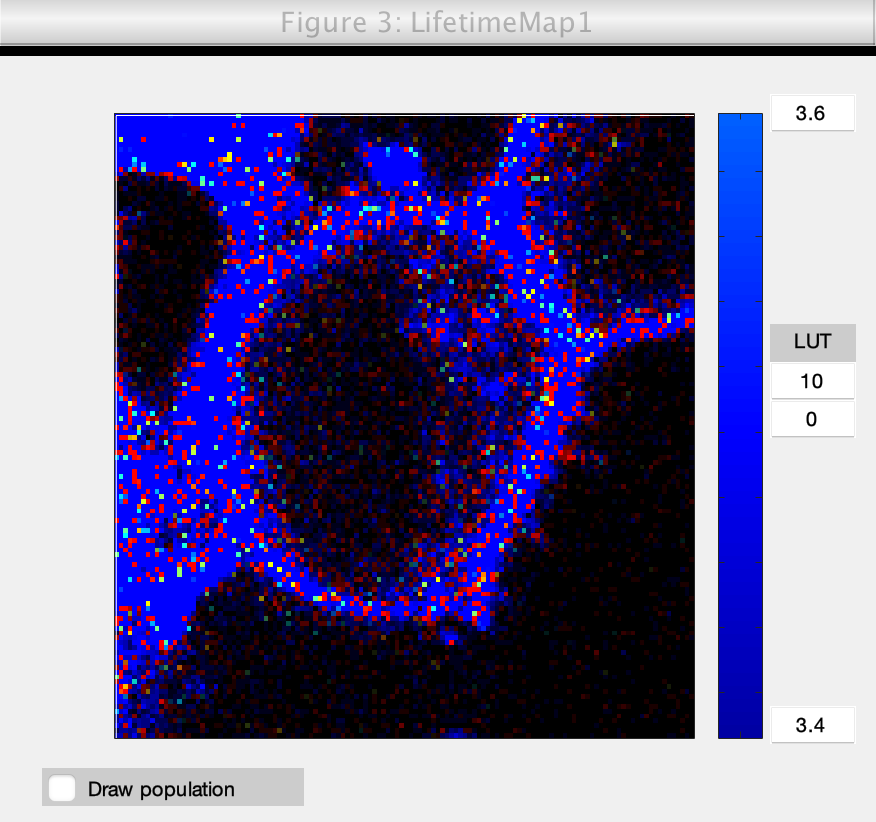

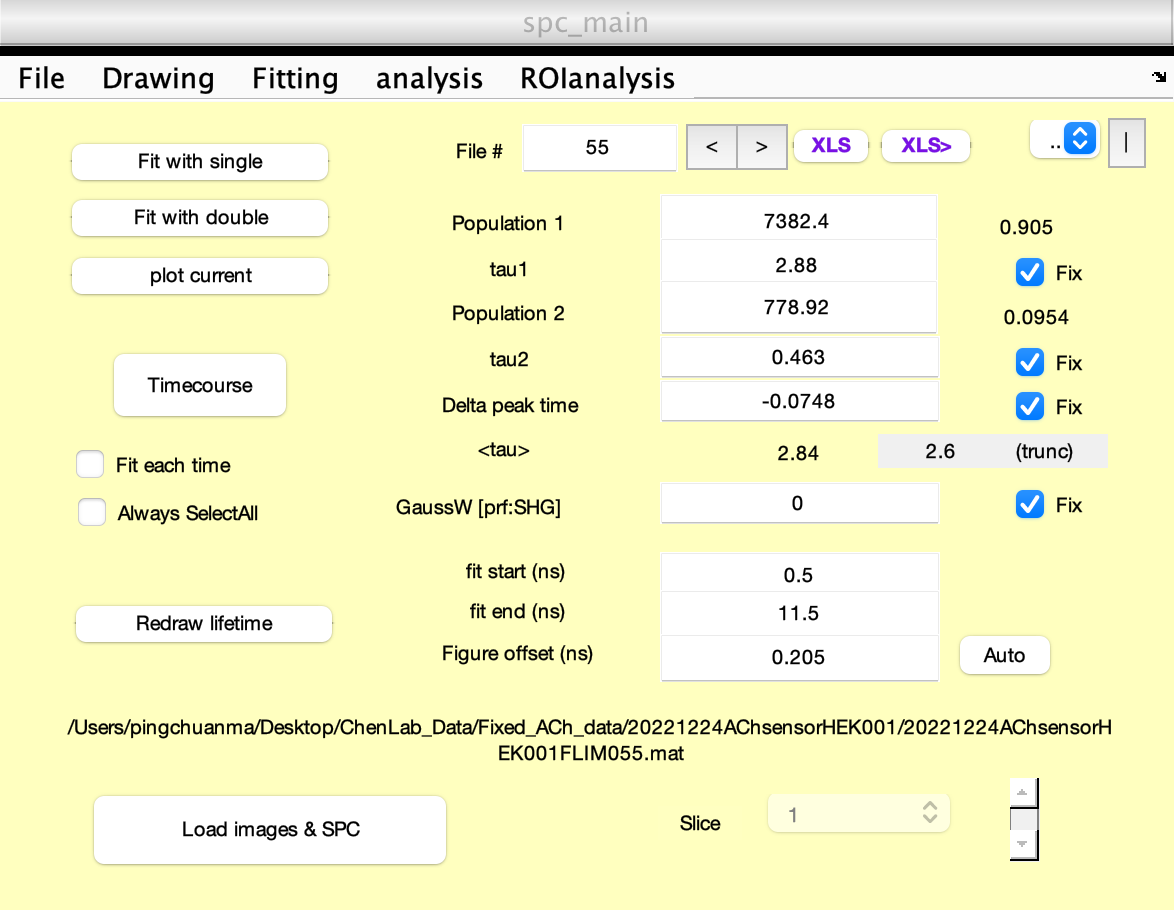

load('simulation_20221228_v2.mat')

DC=0;
AF=round(AF_pixel*ROIsize_ACh)

AF = 935

afterpulse=0.0032;
mkdir('ACh_afterpulse_AF_20230308_3')
mkdir('baseline_afterpulse_AF_20230308_3')

for i=1:100
    SaveName=['ACh_afterpulse_AF_20230308_3/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_ACh, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

for i=1:100
    SaveName=['baseline_afterpulse_AF_20230308_3/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_baseline, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

% load the simulated data, calculate the lifetimes
simulated_lft_ACh_AF=[];
simulated_lft_baseline_AF=[];
lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;

for i=1:100
    SaveName=['ACh_afterpulse_AF_20230308_3/',num2str(i),'.mat'];
    load(SaveName)
    n_final=n_final+backcorr*(photoncount_ACh/samplesize_ACh);
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_ACh=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_ACh_AF(i)=empirical_lft_ACh;
end

for i=1:100
    SaveName=['baseline_afterpulse_AF_20230308_3/',num2str(i),'.mat'];
    load(SaveName)
    n_final=n_final+backcorr*(photoncount_baseline/samplesize_ACh);
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_baseline=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_baseline_AF(i)=empirical_lft_baseline;
end


mean(simulated_lft_ACh_AF)

ans = 3.2480

mean(simulated_lft_baseline_AF)

ans = 3.2407

DC=0;
AF=round(AF_pixel*ROIsize_ACh)

AF = 935

afterpulse=0.0032;
mkdir('ACh_afterpulse_AF_20230308_4')
mkdir('baseline_afterpulse_AF_20230308_4')

for i=1:100
    SaveName=['ACh_afterpulse_AF_20230308_4/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_ACh, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

for i=1:100
    SaveName=['baseline_afterpulse_AF_20230308_4/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_baseline, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

% load the simulated data, calculate the lifetimes
simulated_lft_ACh_AF=[];
simulated_lft_baseline_AF=[];
lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;

for i=1:100
    SaveName=['ACh_afterpulse_AF_20230308_4/',num2str(i),'.mat'];
    load(SaveName)
    n_final=n_final+backcorr*(photoncount_ACh/samplesize_ACh);
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_ACh=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_ACh_AF(i)=empirical_lft_ACh;
end

for i=1:100
    SaveName=['baseline_afterpulse_AF_20230308_4/',num2str(i),'.mat'];
    load(SaveName)
    n_final=n_final+backcorr*(photoncount_baseline/samplesize_ACh);
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_baseline=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_baseline_AF(i)=empirical_lft_baseline;
end


mean(simulated_lft_ACh_AF)

ans = 3.2477

mean(simulated_lft_baseline_AF)

ans = 3.2411